# 演習6-1 中点則による数値積分

•ファイルの最期にあるmidpoint関数(中点則)を完成させなさい．

•以下の厳密解（1.0）をもつ積分を数値計算しなさい. 


$$I_{\sin } =\int_0^{\frac{\pi }{2}} \sin \left(x\right)\textrm{dx}$$



$$I_{\sin } ={\left\lbrack -\cos \left(x\right)\right\rbrack }_0^{\frac{\pi }{2}} =1\ldotp 0$$


•分点数mを[10 , 100, 1000];として絶対誤差を計算しなさい

m=[10, 100, 1000];
Iext=ones(size(m));     % 厳密解(1.0)の配列

Iext =      1     1     1


Imid=zeros(size(m));    % 中点則の計算結果用の配列
n=size(m,2);
% 分点数を変えて積分
for k=1:n
Imid(k)=midpoint(@integrand,0,pi/2,m(k)); 
end
%　絶対誤差
format shortE;
Emid=abs(Iext-Imid)

Emid =    1.0288e-03   1.0281e-05   1.0281e-07


# 演習6-2 台形則による数値積分

•ファイルの最期にあるtrapezoid関数(台形則)を完成させ，6－1と同じ積分を実行しなさい. 

•分点数mを10 , 100, 100として絶対誤差，相対誤差，10進有効桁数を計算しなさい

% m=[10, 100, 1000];
Iext=ones(size(m));     % 厳密解(1.0)の配列
Itrp=zeros(size(m));    % 台形則の計算結果用の配列
n=size(m,2);
% 分点数を変えて積分
for k=1:n
Itrp(k)=trapezoid(@integrand,0,pi/2,m(k)); 
end
%　絶対誤差
format shortE;
Etrp=abs(Iext-Itrp)

Etrp =    2.0570e-03   2.0562e-05   2.0562e-07


# 演習6-3 シンプソン則による数値積分

•ファイルの最期にあるsimpson関数(シンプソン則)を完成させ，6－1と同じ積分を実行しなさい. 

•分点数mを10 , 100, 1000として絶対誤差，相対誤差，10進有効桁数を計算しなさい

% m=[10, 100, 1000];
Iext=ones(size(m));     % 厳密解(1.0)の配列
Ismp=zeros(size(m));    % シンプソン則の計算結果用の配列
n=size(m,2);
% 分点数を変えて積分
for k=1:n
Ismp(k)=simpson(@integrand,0,pi/2,m(k)); 
end
%　絶対誤差
format shortE;
Esmp=abs(Iext-Ismp)

Esmp =    3.3922e-06   3.3824e-10   3.6637e-14


# 演習6-4 対数プロットによる誤差表示

•6－1，2，3の誤差を対数プロットでグラフにしなさい

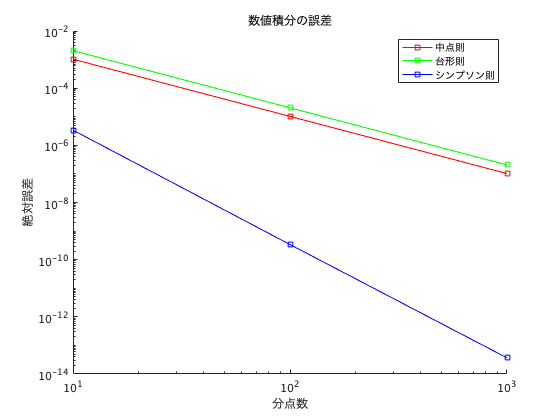

% 両対数グラフの指定
hold on;
plot(m, Emid, 'r-s'); % 中点則は赤色(r)
plot(m, Etrp, 'g-s'); % 台形則は緑色(b)
plot(m, Esmp, 'b-s'); % シンプソン則は青色(b)
graph=gca;             % グラフハンドルの取得
graph.YScale='log';    % y軸対数スケールの設定
graph.XScale='log';    % x軸対数スケールの設定
xlabel('分点数'); 
ylabel('絶対誤差');
legend('中点則','台形則','シンプソン則');
title('数値積分の誤差')
hold off;

# ファイルの最後に関数定義を記述

被積分関数

function fout = integrand(x)
fout = sin(x);
end


中点則，台形則，シンプソン則

function Mm = midpoint(f,a,b,m)
% 中点則　trapezoid
% 関数f(x), 区間[a, b], m個分割
h = (b - a) / m;
ci = a + h/2;
Mm=0;
for i = 0:m-1
    Mm = Mm + f(ci);
    ci = ci + h;
end
Mm=Mm*h;
end

function Tm = trapezoid (f,a,b,m)
% 台形則　trapezoid
% 関数f(x), 区間[a, b], m個分割
h = (b - a) / m;
ai = a + h;
Tm=(f(a)+f(b))/2;
for i = 1:m-1
    Tm = Tm+f(ai);
    ai = ai + h;
end
Tm=Tm*h;
end

function Sm = simpson (f,a,b,m)
% シンプソン則　simpson
% 関数f(x), 区間[a, b], m個分割
% 中点則と台形則を計算
  Mm= midpoint(f, a, b, m/2);
  Tm= trapezoid(f, a, b, m/2);
  Sm= (2/3 * Mm) + (1/3 * Tm);
% 中点則と台形則の結果を合成
% 穴埋め
end